# Postprocessing results

Compare with results in the paper arXiv:1807.10300v3, *Discovering physical concepts with neural networks*, Raban Iten et al., page 12

## Load training results

close("all"); clear; clc;
load("results.mat", "netEncoder", "netDecoder", "latentDimension", "physicalParameters");

## Prediction given one time series

### Generate and plot a time series given parameters compatible with the training data

k = physicalParameters.kMin;
b = physicalParameters.bMin;
m = physicalParameters.m;
A0 = physicalParameters.A0;
delta0 = physicalParameters.delta0;
NTimes = 100;
Tfinal = 10;
[position, time] = generatePendulumTimeSeries(NTimes, Tfinal, k, b, m, A0, delta0);

### Define observations and run encoder

observations = position(time <= 5);
observationsTime = time(time <= 5);

dlObservations = dlarray(zeros(length(observations), 1, 1, 1), "SSCB");
dlObservations(:, 1, 1, 1) = observations;
latentRepresentation = forwardEncoder(netEncoder, dlObservations);

### Decode using mean values from the activations of the latent neurons

mu = latentRepresentation(1:latentDimension, :, :, :);
questions = dlarray(time, "SSCB");
for ii = length(questions) : -1 : 1
    answers(ii) = forwardDecoder(netDecoder, mu, questions(ii));
end

### Plot results

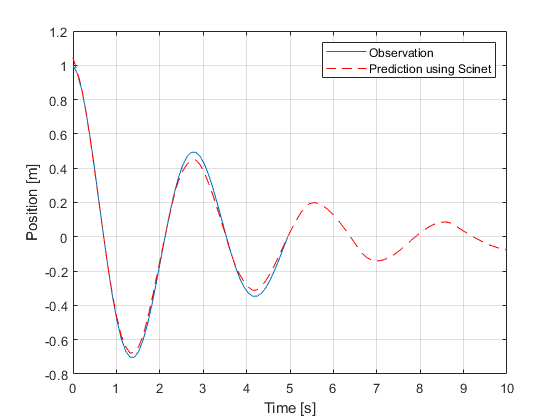

figure
plot(observationsTime, observations);
hold("on");
plot(squeeze(double(extractdata(questions))), squeeze(double(extractdata(answers))), "r--");
grid("on");
xlabel("Time [s]");
ylabel("Position [m]");
legend("Observation", "Prediction using Scinet");

## Activations

### Sweep through the b-k parameter space to show latent neuron activations

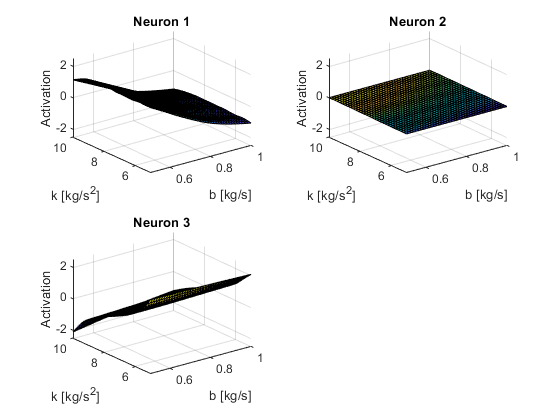

nbv = 40; 
nkv = 30;
bv = linspace(physicalParameters.bMin, physicalParameters.bMax, nbv);
kv = linspace(physicalParameters.kMin, physicalParameters.kMax, nkv);
[B, K] = meshgrid(bv, kv);
Activations = zeros(nkv, nbv, latentDimension);

for ib = 1 : nbv
    for ik = 1 : nkv
        
        % Generate observations 
        [position, time] = generatePendulumTimeSeries(NTimes, Tfinal, kv(ik), bv(ib), m, A0, delta0);
        observations = position(time <= 5);
        dlObservations = dlarray(zeros(length(observations), 1, 1, 1), "SSCB");
        dlObservations(:, 1, 1, 1) = observations;
        
        % Run encoder
        latentRepresentation = forwardEncoder(netEncoder, dlObservations);
        
        % Compute neuron activations (extract mean)
        mu = latentRepresentation(1:latentDimension, :, :, :);

        % Store in the Activations matrix
        Activations(ik, ib, :) = double(extractdata(mu));
        
    end
end

figure
tiledlayout(2,2);
for ia = 1 : latentDimension
    nexttile;
    surf(B, K, Activations(:, :, ia));
    xlabel("b [kg/s]");
    ylabel("k [kg/s^2]");
    zlabel("Activation");
    title("Neuron "+ia);
    zlim([-2.5, 2.5]);
    grid("on");
end

### Conclusion

The plots show the activations of the three latents neurons of SciNet as function of k (spring constant) and b (damping factor).

They indicate that one neuron activation is close to zero, suggesting that only two physical variables are required. Another interesting fact with the remaining two neurons is that one appears to be strongly correlated almost linearly to the spring factor, and the other one to the damping factor. SciNet recognizes that only 2 parameters are needed to encode this situation, and recovers the same time-independent parameters b and k used by physicists.

Copyright 2021 The MathWorks, Inc.